# Yahu's Cone Detector

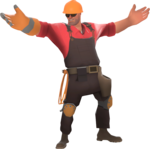

Eliyahu Suskind, 3/28/2023, Rev 1.

% Clean Up Before Running CV
clc
clear
close all

% Initiate webcam and set balance mode
camList = webcamlist

camList = 2×1 cell array
    {'BisonCam, NB Pro'             }
    {'Microsoft® LifeCam Cinema(TM)'}


roboCam = webcam(2)

roboCam =   webcam with properties:

                     Name: 'Microsoft® LifeCam Cinema(TM)'
     AvailableResolutions: {'640x480'  '640x360'  '424x240'  '352x288'  '320x240'  '176x144'  '160x120'  '1280x720'  '960x544'  '800x448'  '800x600'}
               Resolution: '640x480'
                 Exposure: -6
             WhiteBalance: 4500
             ExposureMode: 'auto'
                    Focus: 3
                 Contrast: 5
                Sharpness: 25
                     Tilt: 0
                     Zoom: 0
               Brightness: 100
                FocusMode: 'auto'
         WhiteBalanceMode: 'auto'
    BacklightCompensation: 0
                      Pan: 0
               Saturation: 83


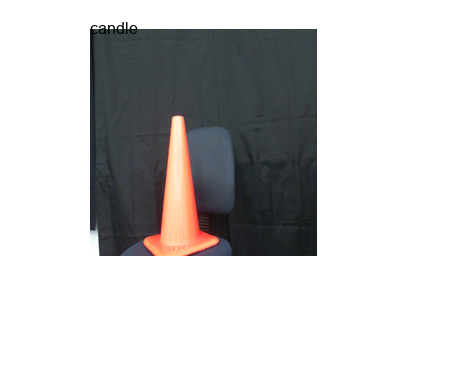

roboCam.WhiteBalanceMode = "manual";
roboCam.Brightness = 100;
myNN = alexnet;
camShow = imshow(zeros(277, 277, 3, 'uint8'));

% Initialize frames
frames = 2000;
oldLabel = "";
currFrameLabel = text(0,0,"");


% Run Live Cam
for i = 1:frames
    
    label = nn_detector(roboCam, myNN, camShow);
    if oldLabel ~= label
        delete(currFrameLabel);
        oldLabel = label;
        currFrameLabel = text(0,0,label);
    end

end

function label = nn_detector(roboCam, myNN, camShow)

    % Capture and classify current frame 
    currFrame = roboCam.snapshot;
    currFrameFin = imresize(currFrame,[227 227]);
    label = classify(myNN,currFrameFin);

    % Draw current frame and label
    set(camShow,'CData',currFrameFin);
    drawnow;

end

function cleanImage = pixel_detector(roboCam, myFigure, testPixels)

% Create filtered webcam image, prompt user input
robotImage = snapshot(roboCam);
[targetMask, orangeMasked] = orangeMask(robotImage);
figure(myFigure)
clc;

% Fill noise in filtered image
cleanImage = bwareaopen(targetMask,testPixels);
figure(myFigure)
clc;

end